# Terahertz band in Body-communication Simulator 

## Description

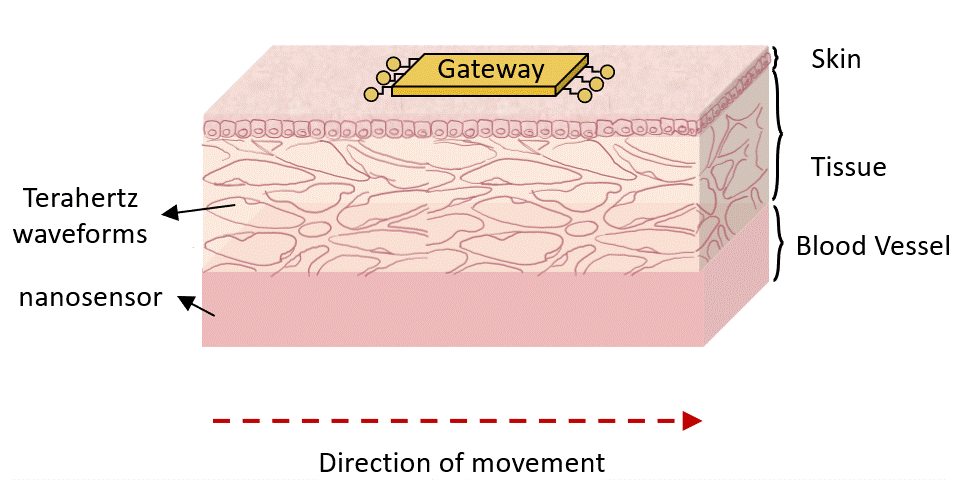

Figure 1: System model.

This code aims to simulate the communication performance between traveling nanosensors in the blood flow and external wearables, as depicted in Fig. 1. The communication is produced in the terahertz band. It takes into account the impact of mobility as the Doppler effect. The modulation format is the binary phase shift keying (BPSK). 

#### Communication Channel Model

The communication channel between the nanosensor and the Gateway is modeled according to the equation [1]:

$r(t)=g_d\,s(t-\tau_d)\,e^{j2\pi\nu t}$, (1)

where $g_d$ is the channel gain, $\tau_d$ is the propagation delay, and $\nu$ is the Doppler frequency as:

$\nu=v\cos(\phi)\frac{f_c}{c_0}$. (2)

In Eq. (2) $v$ is the velocity of the nanosensor, $c_0$ is the propagation speed of the waveform (speed of light), $f_c$ is the carrier frequency, and $\phi$ is the angle of arrival of the wave relative to the direction of motion of the nanosensor, as depicted in Fig. 2.

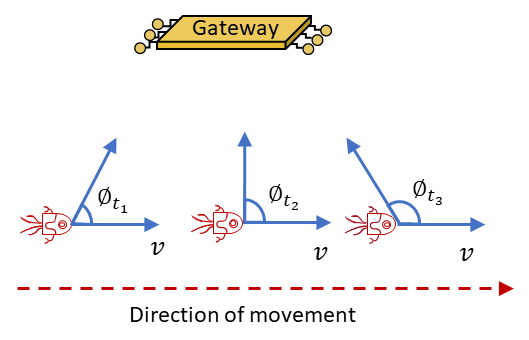

Figure 2: Description of the angle of emissions from the nanosensors along the vessel.

This interface provides adjustable parameters regarding the center frequency for communications, and distance parameters such as the tissue and vessel thickness, as well as the communication range given by the distance between the nanosensor and the Gateway, see Fig. 3. The communication range is always between the minimum and maximum distance lengths.

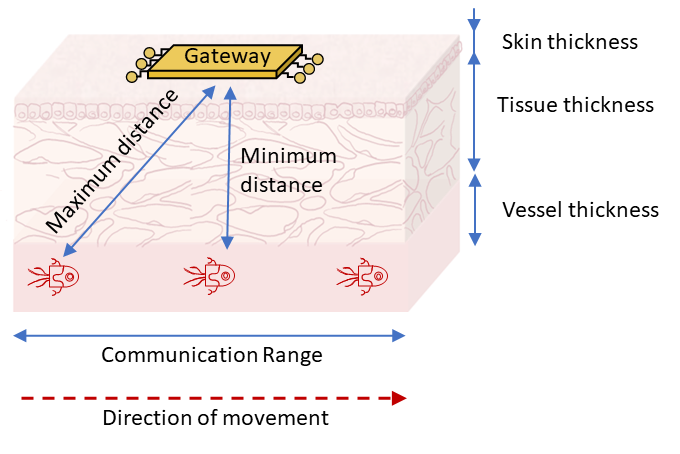

Figure 3: Representation of distances in the tissue.

The communication is modeled in baseband. Constellation points are produced according to the selected waveform (BPSK in this case). The received constellation points are computed after multiplying their amplitude by the channel gain (inverse of the path loss), and rotating the constellation points according to the doppler term (see Eq. (2)) and the transmission delay (negligible for the wireless communication in the milli-meter distance).

#### **Mobility model**

The animation in Fig. 4 illustrates the nanosensor's movement along the vessel. The nanosensor moves from left to right following a straight trajectory. The speed of the nanosensor follows the blood speed defined in the Parameters section of this code. 

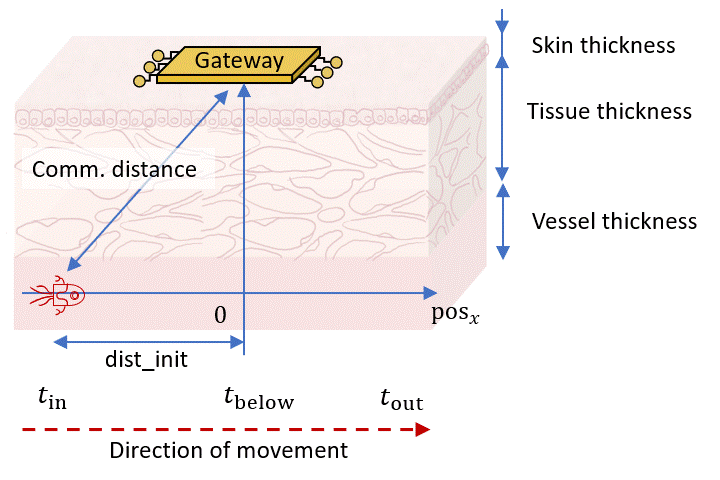

Figure 4: Reference system to evaluate the movement of the nanosensor.

#### Outputs

Outputs are provided regarding the communication scheme as:

- The channel gain versus time: $g_d$ in (1). This is evaluated using the reference in [2].

- The Doppler frequency: $\nu$ according to (2).

- Emmited constellation points.

- Received constellation points

- The achievable bit error rate (BER) versus time.

#### How to run this code

This code runs directly when clicking the run button or updating the parameters below. This code calls to functions implemented in C/C++ (see terahertz.c and terahertz.h). The functions defined in these two files simulate and evaluate the communication system. To re-build these functions, it is needed to install the [MinGW-w64 Compiler (free)](https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html) and to uncomment lines in the compiling block below.

## Parameters

#### **Physiological  Parameters**

**Tissue and Vessel Thickness in meters, see Fig. 3: **

Skin_thickness =86*10^(-6); %Epidermis, further details in [4]
Tissue_thickness=1440*10^(-6);%Dermis, further details in [5]
Vessel_thickness= 477*10^(-6);%Vessel, further details in [6]

**Blood speed (m/s):**

blood_speed=0.44*10^(-1); %Blood speed according to [7] (aorta: 0.2 m/s, arteries: 0.1 m/s, veins: 0.03 m/s)

#### **Waveform parameters**

**Carrier frequency**

 Freq_Hz=0.5*10^12;

**Bits emission**

bit_rate_bps=1*10^6;%transmission bit rate in the units of Giga bit per second
total_bits=2^(5)*10^3;%total of bits to transmit in Kbits, uncomment lines 29 and 32 below when adjusting this control
bits = randi([0 1],total_bits,1); %emmited bits

**Communication range (meters)**

The initial position is computed based on the dist_init_x value from the control below, see Fig. 4. Based on its value, the initial comm. distance is determined using the Pythagoras theorem.

dist_init_x=619*10^(-6);%distance to the position below the gateway, see Fig. 4 above
Comm_dist_init=sqrt(dist_init_x^2+(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);

**Waveform**

mod_order="BPSK";
Tx_power_Watts=4*10^3;%typical values are given in [3]
waveform_amplitude=sqrt(Tx_power_Watts);

**Sampling:**

sampling_time=1/bit_rate_bps*10^(-9);

## **Compiling the functions in C code**

%% Uncomment the next three lines when editing the
%% terahertz.c or terahertz.h files or when updating the total of bits to transmitt(total_bits) or the bit rate(bit_rate_bps)
%% choosing the C++ compiler, if not previously installed at the local PC, follow steps to install MinGW-w64 Compiler in Matlab (free) https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html.
% mex -setup C++ 
%% compiling the C code for the path loss
codegen -config:lib pathLoss_interface -args {0,0,0,0,0}

??? Unable to locate 'pathLoss_interface'.

Code generation failed: View Error Report



Error using codegen

codegen -config:mex pathLoss_interface codegen\lib\pathLoss_interface\pathLoss_interface.lib -args {0,0,0,0,0}

%% compiling the C code for Doppler
codegen -config:lib doppler_interface -args {0,0,0,0,0,0}
codegen -config:mex doppler_interface codegen\lib\doppler_interface\doppler_interface.lib -args {0,0,0,0,0,0}

%% compiling the C code for transceiver and communication
%% uncomment the two lines below when adjusting the control for the total of bits.
codegen -config:lib transceiver_interface -args {0,0,0,0,0,0,0,bits,0,0}
codegen -config:mex transceiver_interface codegen\lib\doppler_interface\doppler_interface.lib -args {0,0,0,0,0,0,0,bits,0,0}


## **Communication Performance**

#### **Nanosensor Mobility**

%evaluating the time dimension
% t_in=0;
% t_out=2*dist_init_x/blood_speed;
% time_vector=linspace(t_in,t_out,1000);
time_vector=0:1/bit_rate_bps:1/bit_rate_bps*(total_bits-1);

%evaluating the spatial dimension
%initial position
pos_o=-sqrt(Comm_dist_init^2-(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);
%position with time
pos_x_nanosensor=pos_o+blood_speed*time_vector;
%communication distance with time
comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);

%plotting
figure;
fontsize=20;
plot(time_vector,comm_dist_time*10^(3),'LineWidth',2); grid on;
xlabel('time [s]','Interpreter','latex');
ylabel('Comm. distance [mm]','Interpreter','latex');
set(gca,'FontSize',fontsize);


#### **Channel Model**

**Pass Loss**

pathLoss_dist_dB=zeros(1,length(comm_dist_time));
for dist=1:length(comm_dist_time)
    %calling to the pre-compiled C function
    pathLoss_dist_dB(dist)=pathLoss_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,Vessel_thickness);
end

%plotting
figure;
plot(time_vector,pathLoss_dist_dB,'LineWidth',2); grid on;
xlabel('time [s]','Interpreter','latex');
ylabel('Path loss [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);


#### Doppler

nu_vector=zeros(1,length(time_vector));

for dist=1:length(nu_vector)
    nu_vector(dist)=doppler_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,Vessel_thickness,blood_speed);
end

figure;
plot(time_vector,mod(nu_vector,pi),'LineWidth',2); grid on
xlabel('time [s]','Interpreter','latex');
ylabel('Doppler term $\nu$','Interpreter','latex');
set(gca,'FontSize',fontsize);


#### Constellations

if(mod_order=="BPSK")
    mod_order_int=2;
elseif(mod_order=="QPSK")
    mod_order_int=4;
else
    mod_order_int=2;%default option is BPSK
end
[Const_Tx_real, Const_Tx_imag, Const_Rx_real, Const_Rx_imag, nanosensor_pos_x]=transceiver_interface_mex(Freq_Hz,dist_init_x,Skin_thickness,Tissue_thickness,Vessel_thickness,blood_speed,mod_order_int,bits,bit_rate_bps,waveform_amplitude);


%plotting constellation points
figure;
plot(waveform_amplitude*cos(0:0.01:2*pi),waveform_amplitude*sin(0:0.01:2*pi),'--','Color','black'); hold on;
plot(Const_Tx_real,Const_Tx_imag,'o','Color','#0072BD','LineWidth',2); grid on;
title('Transmission','Interpreter','latex');
set(gca, 'XTick', [-max(Const_Tx_real) 0 max(Const_Tx_real)]);
set(gca, 'XTickLabel', {'$-A_{Tx}$','$0$','$A_{Tx}$'}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [-max(Const_Tx_real) 0 max(Const_Tx_real)]);
set(gca, 'YTickLabel', {'$-A_{Tx}$','$0$','$A_{Tx}$'}, 'TickLabelInterpreter', 'latex');
xlabel('In Phase','Interpreter','latex');
ylabel('Quadrature','Interpreter','latex');
axis([-1.1*max(Const_Tx_real) 1.1*max(Const_Tx_real) -1.1*max(Const_Tx_real) 1.1*max(Const_Tx_real)]);
axis square
set(gca,'FontSize',fontsize);

figure;
plot(abs(Const_Rx_real(1))*cos(0:0.01:2*pi),abs(Const_Rx_real(1))*sin(0:0.01:2*pi),'--','Color','black'); hold on;
plot(Const_Rx_real(1:5*10^2),Const_Rx_imag(1:5*10^2),'o','Color','#0072BD','LineWidth',2); grid on;
title('Reception','Interpreter','latex');
set(gca, 'XTick', [-abs(Const_Rx_real(1)) 0 abs(Const_Rx_real(1))]);
set(gca, 'XTickLabel', {'$-A_{Rx}$','$0$','$A_{Rx}$'}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [-abs(Const_Rx_real(1)) 0 abs(Const_Rx_real(1))]);
set(gca, 'YTickLabel', {'$-A_{Rx}$','$0$','$A_{Rx}$'}, 'TickLabelInterpreter', 'latex');
xlabel('In Phase','Interpreter','latex');
ylabel('Quadrature','Interpreter','latex');
axis([-1.1*abs(Const_Rx_real(1)) 1.1*abs(Const_Rx_real(1)) -1.1*abs(Const_Rx_real(1)) 1.1*abs(Const_Rx_real(1))]);
axis square
set(gca,'FontSize',fontsize);

## Parameter sweep plots

#### Path Loss

%frequency in the terahertz band
Freq_THz_vector=(0.1:0.1:5)*10^12;
%Thickness of Skin, Tissue, and Vessel
Skin_thickness = 76*10^(-6);
Tissue_thickness = 1022*10^(-6);
Vessel_thickness = 200*10^(-6);
%communication distance with time, see Fig. 4
Comm_dist_vector=(Skin_thickness+Tissue_thickness+Vessel_thickness):10^(-4):6*10^(-3);

%pre-allocating the channel gain matrix
pathLoss_matrix_dB=zeros(length(Freq_THz_vector),length(Comm_dist_vector));

%computing the path loss
for f=1:length(Freq_THz_vector)
    for dist=1:length(Comm_dist_vector)
        %calling to the pre-compiled C function
        pathLoss_matrix_dB(f,dist)=pathLoss_interface_mex(Freq_THz_vector(f),Comm_dist_vector(dist),Skin_thickness,Tissue_thickness,Vessel_thickness);
    end
end

for dist=1:length(comm_dist_time)
    %calling to the pre-compiled C function
    pathLoss_dist_dB(dist)=pathLoss_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,Vessel_thickness);
end

%plotting
figure;
[F,D]=meshgrid(Freq_THz_vector/10^(12),Comm_dist_vector/10^(-3));
mesh(F,D,pathLoss_matrix_dB'); hold on; 
marker_indices=1:100:length(comm_dist_time)/2;
plot3(Freq_Hz/10^(12)*ones(1,length(comm_dist_time)/2),comm_dist_time(1:end/2)/10^(-3),pathLoss_dist_dB(1:end/2),'-o','MarkerIndices',marker_indices,'LineWidth',1.5,'MarkerFaceColor','#0072BD','MarkerSize',12);
xlabel('Frequency [THz]','Interpreter','latex');
ylabel('Distance [mm]','Interpreter','latex');
zlabel('Path Loss [dB]','Interpreter','latex');
legend({'Path loss surface','Traveling path'},'Interpreter','latex');
set(gca,'FontSize',fontsize);


## testing

**Path loss**

% %running the C code for the path loss
% pathLoss_interface_mex(Freq_THz,Comm_dist_init,Skin_thickness,Tissue_thickness,Vessel_thickness);
% 

**Doppler**

% %running the C code for the Doppler term
% doppler_interface_mex(Freq_THz,Comm_dist_init,Skin_thickness,Tissue_thickness,Vessel_thickness,blood_speed);

## **References**

[1] G. Matz and F. Hlawatsch, “Fundamentals of Time-Varying Communication Channels,” in Wireless Communications Over Rapidly Time-Varying Channels, F. Hlawatsch and G. Matz, Eds., Elsevier, 2011, pp. 1–63.

[2] J. Simonjan, B. D. Unluturk and I. F. Akyildiz, "In-Body Bionanosensor Localization for Anomaly Detection via Inertial Positioning and THz Backscattering Communication," in IEEE Transactions on NanoBioscience, vol. 21, no. 2, pp. 216-225, April 2022, doi: 10.1109/TNB.2021.3123972.

[3] J. M. Jornet and I. F. Akyildiz, "Channel Modeling and Capacity Analysis for Electromagnetic Wireless Nanonetworks in the Terahertz Band," in IEEE Transactions on Wireless Communications, vol. 10, no. 10, pp. 3211-3221, October 2011, doi: 10.1109/TWC.2011.081011.100545.

[4] G. Piro, P. Bia, G. Boggia, D. Caratelli, L.A. Grieco, L. Mescia, "Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities," Nano Communication Networks, Volume 10, 2016, Pages 51-59, ISSN 1878-7789, [https://doi.org/10.1016/j.nancom.2016.07.010.](https://doi.org/10.1016/j.nancom.2016.07.010.)

[5] P. Oltulu, B. Ince, N. Kokbudak, F. Kılıc¸ ¨ et al., “Measurement of epidermis, dermis, and total skin thicknesses from six different body regions with a new ethical histometric technique,” Turk Plastik, Rekonstr ¨ uktif ve ¨ Estetik Cerrahi Dergisi (Turk J Plast Surg), vol. 26, no. 2, pp. 56–61, 2018. DOI: 10.4103/tjps.TJPS_2_17

[6] M. Fruchard, L. Arcese, and E. Courtial, “Estimation of the blood velocity for nanorobotics,” IEEE Transactions on Robotics, vol. 30, no. 1, pp. 93–102, 2013.

[7] A. C. Guyton and M. E. Hall, Guyton and Hall Textbook of Medical Physiology, 14th ed. Elsevier, 2015.